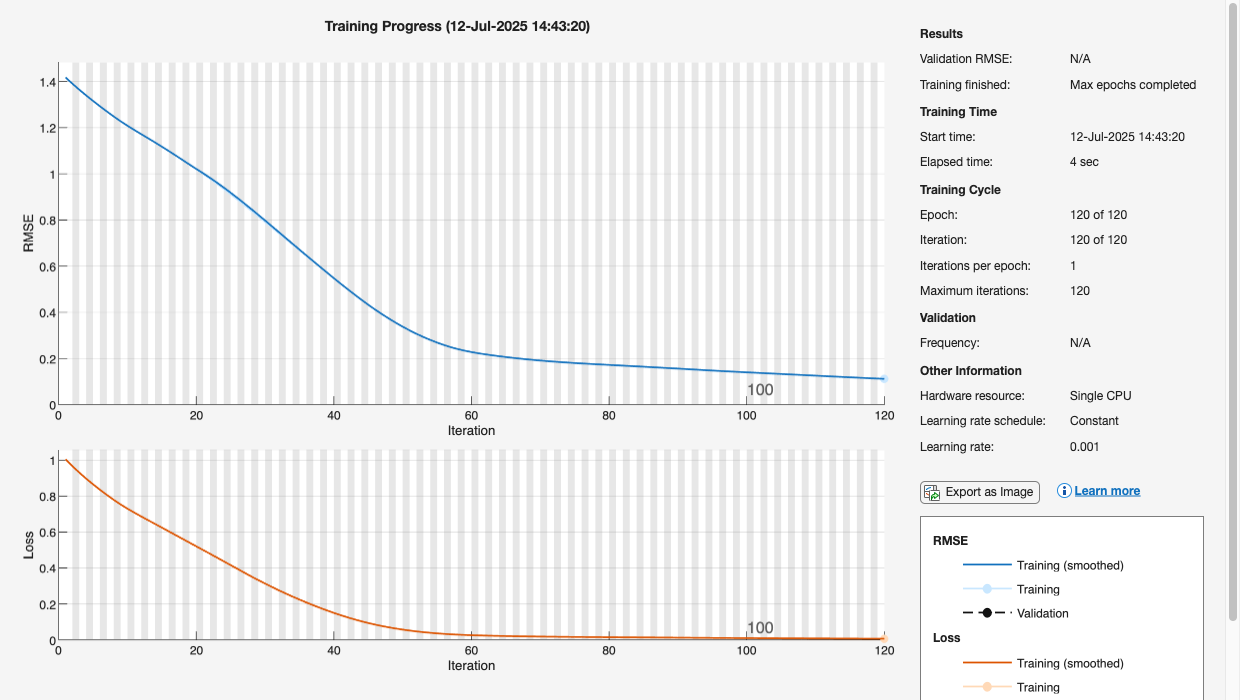

cd('/Users/sushant/Desktop/ITC/JIPITE')
filename = 'MX201 Vibration Data for analysis.xlsx';
data = readtable(filename, 'VariableNamingRule', 'preserve');

data.Properties.VariableNames = {'DateTime','X_RMS','Y_RMS','Z_RMS','XRMS_Trend','YRMS_Trend','ZRMS_Trend'};
data.DateTime = datetime(data.DateTime);

validIdx = data.X_RMS > 0 | data.Y_RMS > 0 | data.Z_RMS > 0;
data = data(validIdx, :);

features = table;
features.XRMS = data.X_RMS;
features.YRMS = data.Y_RMS;
features.ZRMS = data.Z_RMS;
features.XRMS_Trend = data.XRMS_Trend;
features.YRMS_Trend = data.YRMS_Trend;
features.ZRMS_Trend = data.ZRMS_Trend;
features.MagRMS = sqrt(data.X_RMS.^2 + data.Y_RMS.^2 + data.Z_RMS.^2);
features.dXRMS = [NaN; diff(data.X_RMS)];
features.dYRMS = [NaN; diff(data.Y_RMS)];
features.dZRMS = [NaN; diff(data.Z_RMS)];
features = rmmissing(features);  % remove NaNs

X = normalize(features{:,:}, 'range');

numTrain = round(0.5 * size(X, 1));
XTrain = {X(1:numTrain, :)'};  
Xseq   = {X'};                         

%% Define network
layers = [
    sequenceInputLayer(size(X, 2))
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(size(X,2))
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 120, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 1e-3, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress', ...
    'Verbose', false);

%% Train
net = trainNetwork(XTrain, XTrain, layers, options);


%% Predict
Ypred = predict(net, Xseq);
reconLoss = sqrt(mean((Xseq{1} - Ypred{1}).^2, 1));  
timestamps = data.DateTime(end - numel(reconLoss) + 1:end);

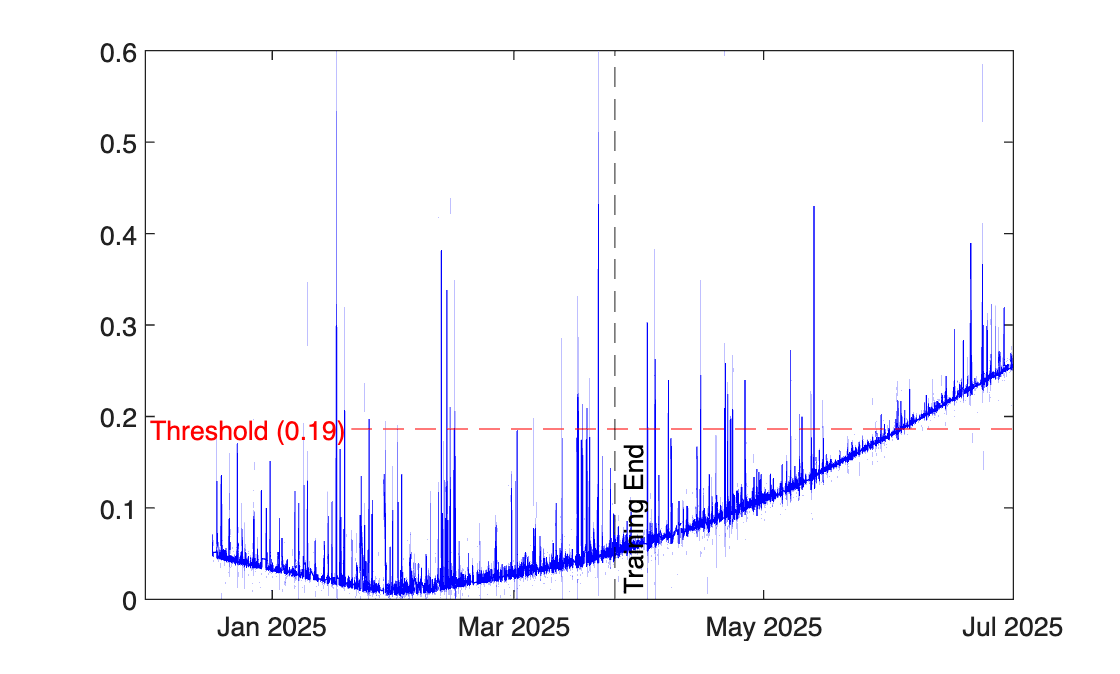


%% Plot
figure;
plot(timestamps, reconLoss, 'b');
hold on;

% Threshold
p = 0.9;  % e.g., use 70% of timeline to compute threshold
N = size(reconLoss, 2);  % total number of samples in reconLoss
cutoffIdx = round(p * N);

threshold = prctile(reconLoss(1:cutoffIdx), 95);
yline(threshold, '--r', sprintf('Threshold (%.2f)', threshold), ...
    'LabelHorizontalAlignment', 'left', 'LabelVerticalAlignment', 'middle');

% Mark end of training
trainEndTime = data.DateTime(numTrain);
xline(trainEndTime, '--k', 'Training End', 'LabelVerticalAlignment','bottom');



% Automatically mark all timestamps where any RMS > 8.5 mm/s
faultIdx = data.X_RMS > 8.5 | data.Y_RMS > 8.5 | data.Z_RMS > 8.5;
faultTimes = unique(data.DateTime(faultIdx));

% for i = 1:numel(faultTimes)
%     xline(faultTimes(i), '--m');
% end

% Reconstruct the mapping between timestamps and RMSE
rmseTimestamps = timestamps;
rmseValues = reconLoss;

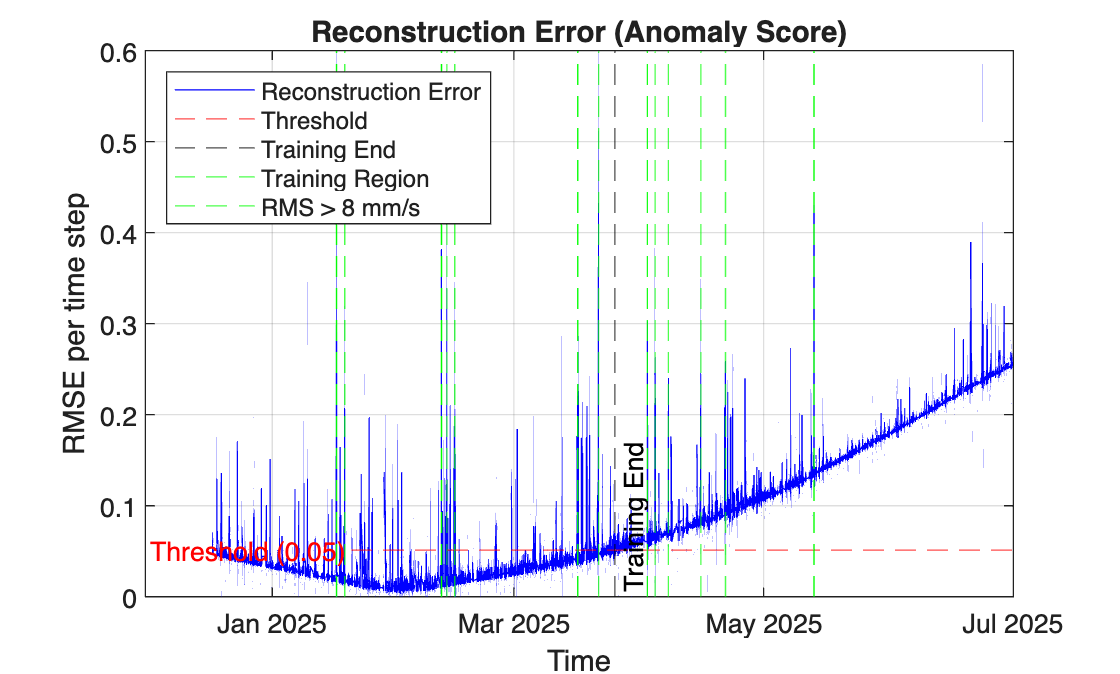


for i = 1:numel(faultTimes)
    faultTime = faultTimes(i);

    % Find exact match (down to the second)
    idx = find(rmseTimestamps == faultTime, 1);

    if ~isempty(idx) && rmseValues(idx) > threshold
        xline(faultTime, '--g');  % GREEN = fault + anomaly
    elseif ~isempty(idx)
        xline(faultTime, '--m');  % MAGENTA = fault only
    else
        xline(faultTime, '--m');  % fallback (no RMSE timestamp match)
    end
end

% Final plot settings
title('Reconstruction Error (Anomaly Score)');
ylabel('RMSE per time step');
xlabel('Time');
legend('Reconstruction Error', 'Threshold', 'Training End', 'Training Region', 'RMS > 8 mm/s', 'Location', 'northwest');
grid on;

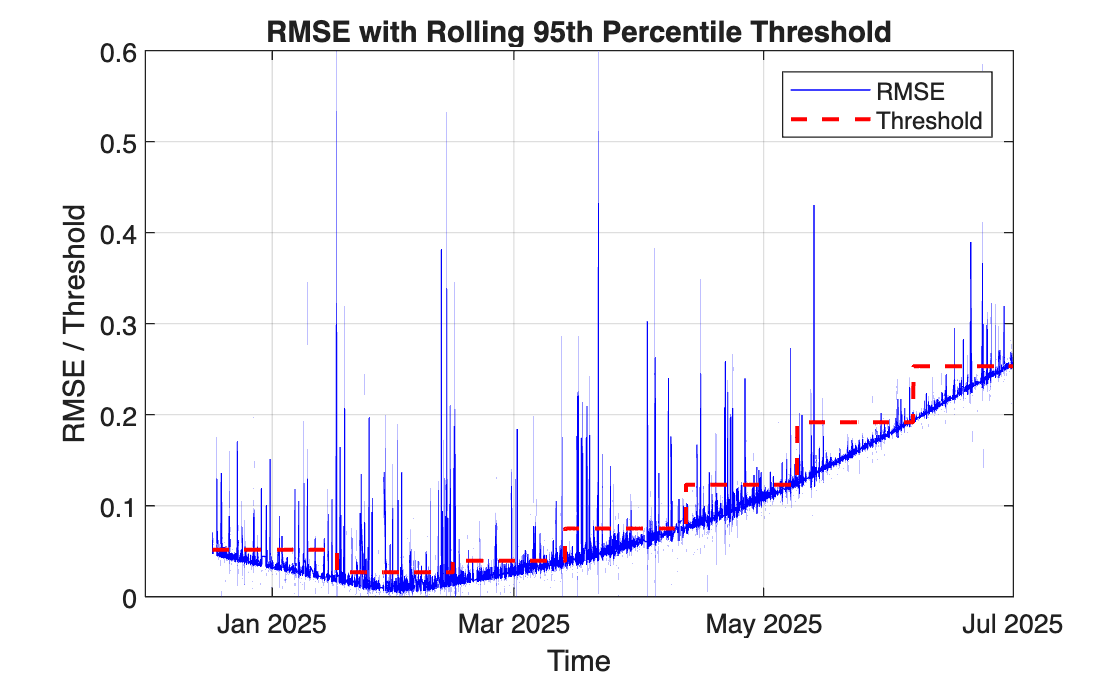

% Initialize
windowSize = 10000;
numWindows = floor(length(reconLoss) / windowSize);
thresholdPer100 = zeros(length(reconLoss), 1);

% Loop over every 100-sample chunk
for i = 1:numWindows
    idxStart = (i-1)*windowSize + 1;
    idxEnd = i*windowSize;

    windowData = reconLoss(idxStart:idxEnd);
    windowThreshold = prctile(windowData, 95);

    thresholdPer100(idxStart:idxEnd) = windowThreshold;
end

% For any remaining points at the end
if idxEnd < length(reconLoss)
    remainingData = reconLoss(idxEnd+1:end);
    remainingThreshold = prctile(remainingData, 95);
    thresholdPer100(idxEnd+1:end) = remainingThreshold;
end

% Append to a new table
rmseTable = table(timestamps(:), reconLoss(:), thresholdPer100(:), ...
    'VariableNames', {'Timestamp', 'RMSE', 'Threshold'});

figure;
plot(rmseTable.Timestamp, rmseTable.RMSE, 'b'); hold on;
plot(rmseTable.Timestamp, rmseTable.Threshold, 'r--', 'LineWidth', 1.5);
xlabel('Time');
ylabel('RMSE / Threshold');
title('RMSE with Rolling 95th Percentile Threshold');
legend('RMSE', 'Threshold');
grid on;

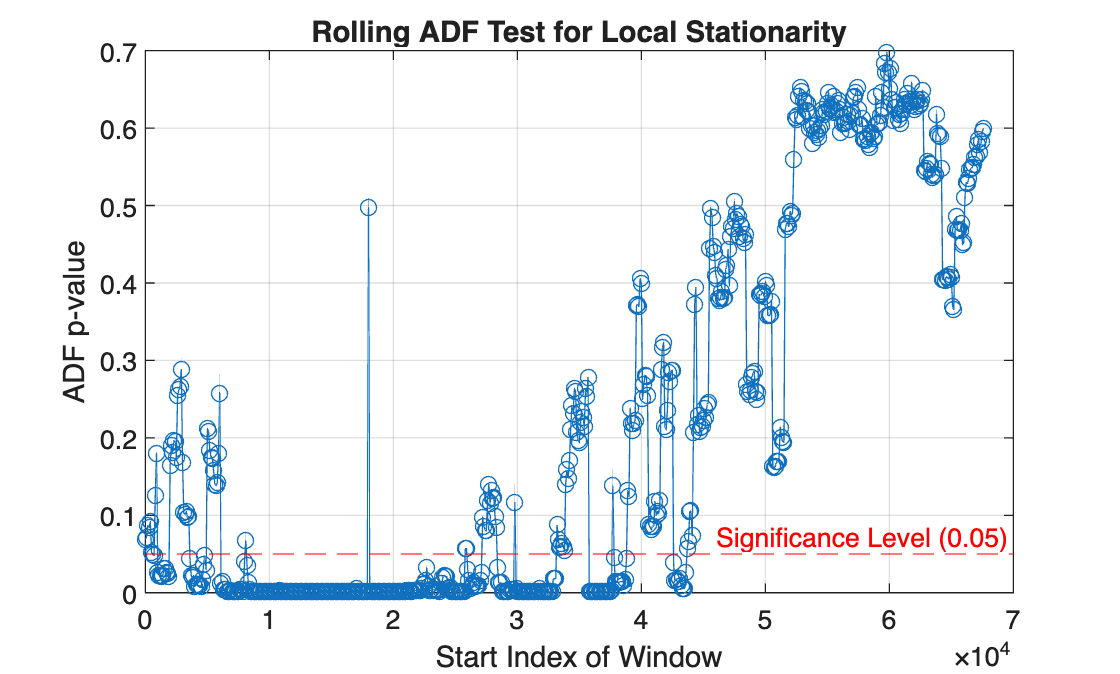

reconLoss = double(reconLoss);  % Add this line once before any analysis
% --- Parameters ---
windowSize = 1000;   % Number of points per rolling window
stepSize = 100;      % Slide the window by this many points
N = length(reconLoss);  % or use 'smoothRMSE' instead

% --- Preallocate ---
pVals = NaN(floor((N - windowSize) / stepSize) + 1, 1);
startIdx = NaN(size(pVals));

% --- Rolling ADF ---
for i = 1:length(pVals)
    idx = (i - 1) * stepSize + 1;
    segment = reconLoss(idx : idx + windowSize - 1);
    
    [~, p] = adftest(double(segment));  % ← FIXED
    pVals(i) = p;
    startIdx(i) = idx;
end

% --- Plot ---
figure;
plot(startIdx, pVals, '-o');
yline(0.05, '--r', 'Significance Level (0.05)');
xlabel('Start Index of Window');
ylabel('ADF p-value');
title('Rolling ADF Test for Local Stationarity');
grid on;

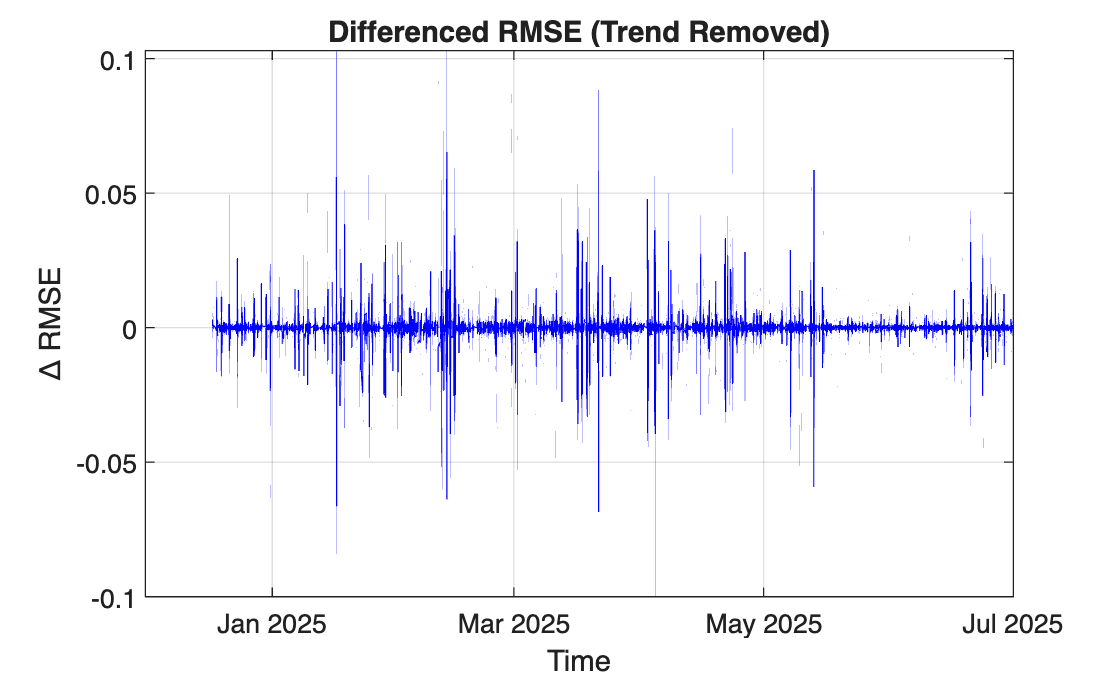

% Remove trend via differencing
diffRMSE = diff(reconLoss);

% Adjust timestamps to align
diffTimestamps = timestamps(2:end);

% Optional: smooth differenced signal
smoothDiffRMSE = movmean(diffRMSE, 5);  % You can change the window size

% Plot
figure;
plot(diffTimestamps, smoothDiffRMSE, 'b');
title('Differenced RMSE (Trend Removed)');
xlabel('Time');
ylabel('Δ RMSE');
grid on;

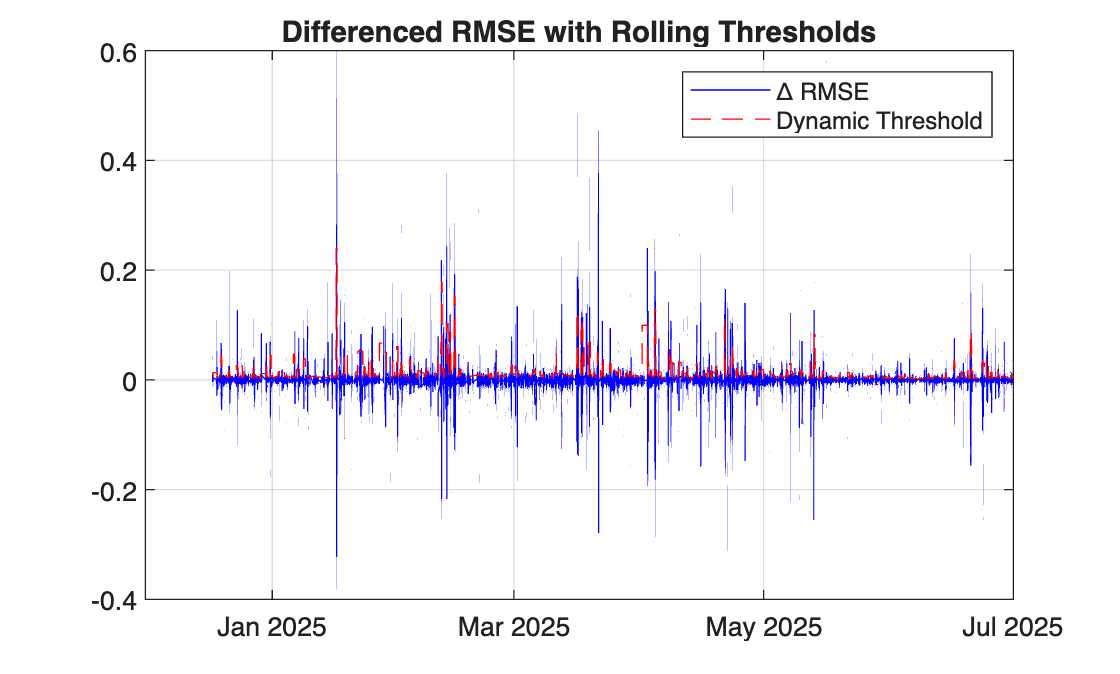

% Parameters
windowSize = 100;
numWindows = floor(length(diffRMSE) / windowSize);
rollingThresholds = zeros(size(diffRMSE));

for i = 1:numWindows
    idxStart = (i-1)*windowSize + 1;
    idxEnd = min(i*windowSize, length(diffRMSE));
    
    segment = diffRMSE(idxStart:idxEnd);
    th = prctile(segment, 98);  % or another quantile
    
    % Assign threshold to this window
    rollingThresholds(idxStart:idxEnd) = th;
end

% Plot
figure;
plot(diffTimestamps, diffRMSE, 'b'); hold on;
plot(diffTimestamps, rollingThresholds, 'r--');
legend('Δ RMSE', 'Dynamic Threshold');
title('Differenced RMSE with Rolling Thresholds');
grid on;